# HW 4 Dominic Riccoboni

## Radiation Constants

h = 6.62607015e-34; %[Js] Planck's constant
KB = 1.380649e-23; %[J/K] Boltzmann constant
C0 = 2.9979e8; %[m/s] Speed of light in vacuum
C1 = h*C0^2 %[Jm^2/s];

C1 = 5.9551e-17

C2 = h*C0/KB; %[m*K]
sigma = 2*C1*pi^5/(15*C2^4);

sigma = 5.6705e-08

## Problem 2.4

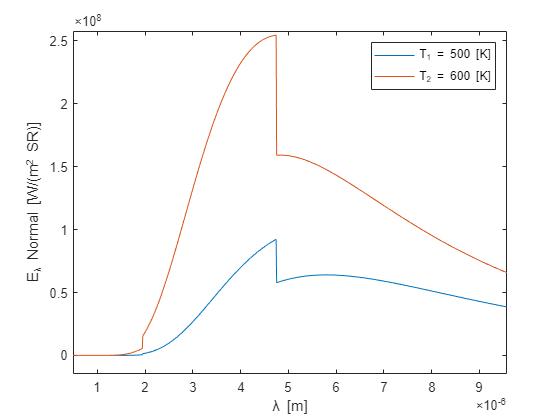

E_lam_b_fun = @(lambda,T) 2*C1./lambda.^5./(exp(C2./(lambda.*T))-1); %Function handle for normal spectral emissive power

n = 1000; %Number of points to plot

lambdas = linspace(0, 10e-6, n); %Domain variable is wavelength

T1 = 500; %500 [K]
T2 = 600; %600 [K]

E_lam_b1 = E_lam_b_fun(lambdas,T1*ones(size(lambdas))); %Evaluate E_lam_b_fun at lambdas and T1
E_lam_b2 = E_lam_b_fun(lambdas,T2*ones(size(lambdas))); %Evaluate E_lam_b_fun at lambdas and T2

%Creat piecewise emissivity data
i_lambda1 = lambdas <= 1.95e-6;
i_lambda2 = (1.95e-6 < lambdas) & (lambdas <= 4.75e-6);
i_lambda3 = 4.75e-6 < lambdas;
emsvty_lam = [0.3*ones(size(lambdas(i_lambda1))), 0.8*ones(size(lambdas(i_lambda2))), 0.5*ones(size(lambdas(i_lambda3)))];

%Plot results
figure
plot(lambdas, emsvty_lam.*E_lam_b1,lambdas, emsvty_lam.*E_lam_b2)
xlabel('\lambda [m]')
ylabel('E_{\lambda} Normal [W/(m^3 SR)]')
legend('T_1 = 500 [K]','T_2 = 600 [K]')

xlim([0.00000000 0.00001000])
ylim([-20991254 279008746])

xlim([0.00000049 0.00000958])
ylim([-14789293 257937980])

%Get lambdas at max emissive power
[E_lam_b1_max, i1] = max(emsvty_lam.*E_lam_b1);

lambda_max1 = lambdas(i1)

lambda_max1 = 4.7447e-06


[E_lam_b2_max, i2] = max(emsvty_lam.*E_lam_b2);

lambda_max2 = lambdas(i2)

lambda_max2 = 4.7447e-06

## Problem 2.5

### Total emissivity at 300 [K]

T1 = 300;

%Spectral emissivitys
e1 = 0.83;
e2 = 0.5;
e3 = 0.17;

%cutoff lambdas (piecewise emissivity)
lam1 = 1.9e-6;
lam2 = 2.8e-6;

%Integrand function handles
Integrand1 = @(lambda) e1*2*pi*C1./lambda.^5./(exp(C2./(lambda*T1))-1);
Integrand2 = @(lambda) e2*2*pi*C1./lambda.^5./(exp(C2./(lambda*T1))-1);
Integrand3 = @(lambda) e3*2*pi*C1./lambda.^5./(exp(C2./(lambda*T1))-1);

%Numerical integration
Total_emsvty = (integral(Integrand1, 0,lam1) + integral(Integrand2, lam1, lam2) + integral(Integrand3, lam2, 1))/(sigma*T1^4)

Total_emsvty = 0.1700

### Total absorptivity at 5780 [K]

T2 = 5780;

%Spectral emissivitys
e1 = 0.83;
e2 = 0.5;
e3 = 0.17;

%cutoff lambdas (piecewise emissivity)
lam1 = 1.9e-6;
lam2 = 2.8e-6;

%Integrand function handles
Integrand1 = @(lambda) e1*2*pi*C1./lambda.^5./(exp(C2./(lambda*T2))-1);
Integrand2 = @(lambda) e2*2*pi*C1./lambda.^5./(exp(C2./(lambda*T2))-1);
Integrand3 = @(lambda) e3*2*pi*C1./lambda.^5./(exp(C2./(lambda*T2))-1);

%Numerical integration
Total_abstvty = (integral(Integrand1, 0,lam1) + integral(Integrand2, lam1, lam2) + integral(Integrand3, lam2, 1))/(sigma*T2^4)

Total_abstvty = 0.7990

## Problem 2.10

### part a

T1 = 750;

lambdas = [0.0001 1 1.5 2 2.5 3 3.5 4 4.5 5 6 7 8 100000]*10^-6;
emsvtys = [0 0 0.2 0.4 0.6 0.8 0.8 0.8 0.7 0.6 0.4 0.2 0 0];
E_lam_bs = 2*pi*C1./lambdas.^5./(exp(C2./(lambdas*T1))-1);

Total_emsvty = trapz(lambdas,emsvtys.*E_lam_bs)/(sigma*T1^4)

Total_emsvty = 0.4168

### part b

T2 = 1600;

